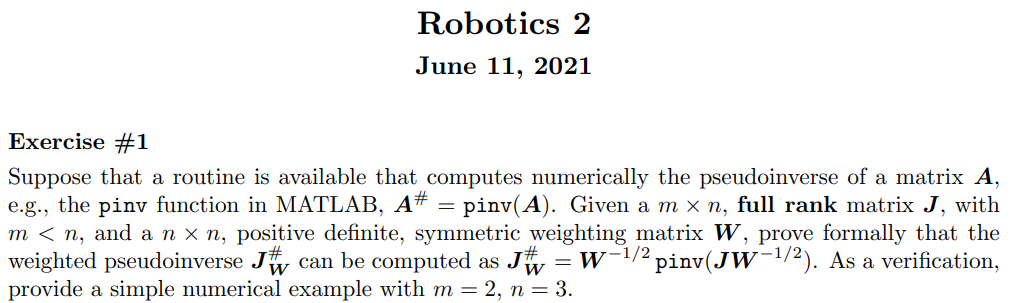

## Exercise 2

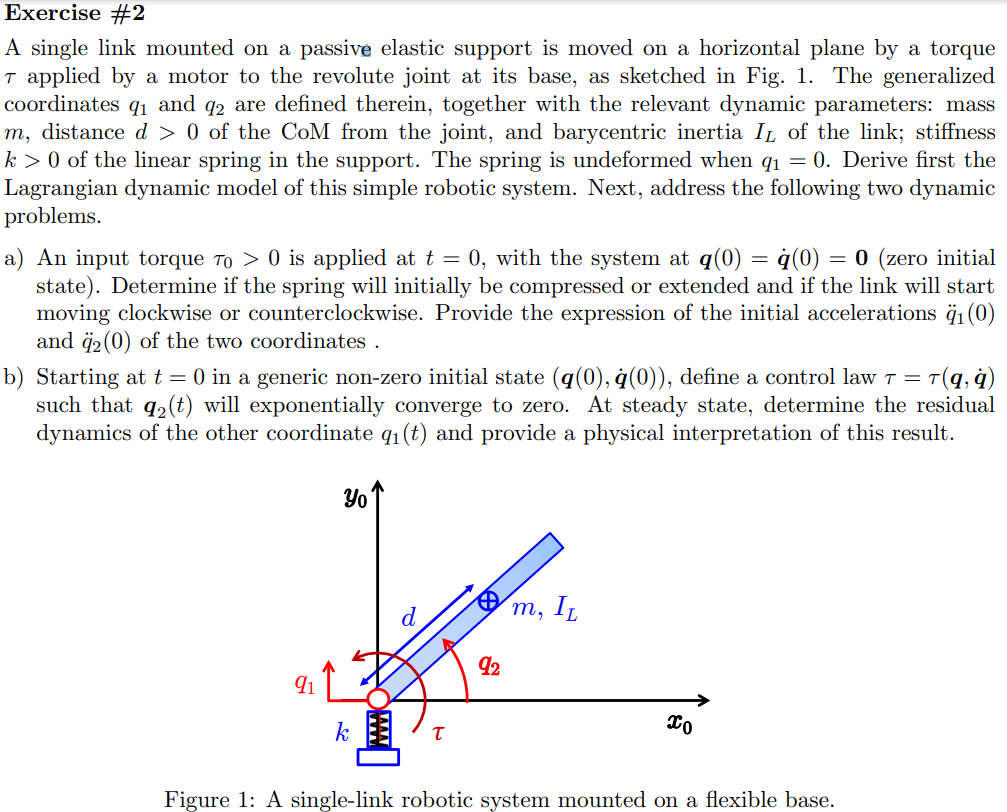

% 
% 
% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [1,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% % alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

% R2Robot=['pr';'yx';sigmaD]

R2Robot = 3×2 char array
    'pr'
    'yx'
    ' '


% z = Gen_param(n);
% z.sigmaD=R2Robot;
% % l(1)=0 %don't do this because dc1 is going to dissaperar
% % z.opt_expr={[l(1)],[0]};%use this instead
% z.opt_expr={[m(1)],[0]};%use this instead
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table, 1 normal mode

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: {[1×1 sym]  [0]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismo

% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% 
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: {[1×1 sym]  [0]}
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismo

% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% % % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% % %             0       , z.l(2)  , 0   , q(2);]

% % % 
% % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: {[1×1 sym]  [0]}
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismo

si falla aquí está el error


$$a = l_{2}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = 0$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} 0 & \frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2} \end{array}\right)$$

$$To\_derive = \left(\begin{array}{cc} 0 & -l_{2}\,\sin\left(q_{2}\left(t\right)\right)\\ 1 & l_{2}\,\cos\left(q_{2}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$Pc = \left(\begin{array}{cc} 0 & {\mathrm{dc}}_{2}\,\cos\left(q_{2}\right)\\ q_{1} & q_{1}+{\mathrm{dc}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{cc} 0 & -{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ {\dot{q}}_{1} & {\dot{q}}_{1}+{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & {\dot{q}}_{2} \end{array}\right)$$

$$T = \frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}$$

$$Ti = \left(\begin{array}{cc} 0 & \frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2} \end{array}\right)$$

$$M = \left(\begin{array}{cc} m_{2} & {\mathrm{dc}}_{2}\,m_{2}\,\cos\left(q_{2}\right)\\ {\mathrm{dc}}_{2}\,m_{2}\,\cos\left(q_{2}\right) & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$

VarShortRobot = struct with fields:
    Pc: [3×2 sym]
    vc: [3×2 sym]
     w: [3×2 sym]
     T: [1×1 sym]
    Ti: [1×2 sym]
     M: [2×2 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×2 sym]
               TPartial: {[4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×2 sym]
    Jacobian_dot_PTotal: [3×2 sym]
               PPartial: {[3×1 sym]  [3×1 sym]}
                     Pc: [3×2 sym]
                RTotali: {[3×3 sym]  [3×3 sym]}
           ThetaPartial: [2×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×2 sym]
                      w: [3×2 sym]
                      T: [1×1 sym]
                     Ti: [1×2 sym]
                      M: [2×2 sym]


% Ti(1)

$$ans = 0$$

% Pc

$$Pc = \left(\begin{array}{cc} 0 & {\mathrm{dc}}_{2}\,\cos\left(q_{2}\right)\\ q_{1} & q_{1}+{\mathrm{dc}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

% M

$$M = \left(\begin{array}{cc} m_{2} & {\mathrm{dc}}_{2}\,m_{2}\,\cos\left(q_{2}\right)\\ {\mathrm{dc}}_{2}\,m_{2}\,\cos\left(q_{2}\right) & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$

% 

## Potential energy definition

% %special potential energy
% k=sym('k','real')

$$k = k$$

% f_u=[(k*z.q(1).^2)/2,0]'

$$f\_u = \left(\begin{array}{c} \frac{k\,{q_{1}}^{2}}{2}\\ 0 \end{array}\right)$$

% isMotor=false

isMotor = logical
   0


% 
% % [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)
% [grad_f,PE, U,grad_f_short,PE_short] = getGradient(f_u,z.q)%,gradient computation

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) \end{array}\right)$$

$$PE = {q_{1}}^{2}\,\frac{k}{2}$$

$$PE\_short = \frac{k\,{q_{1}}^{2}}{2}$$

$$grad\_f\_short = \left(\begin{array}{c} k\,q_{1}\\ 0 \end{array}\right)$$

$$grad\_f = \left(\begin{array}{c} k\,q_{1}\\ 0 \end{array}\right)$$

$$PE = {q_{1}}^{2}\,\frac{k}{2}$$

U = 1×1 cell array
    {1×1 sym}


$$grad\_f\_short = \left(\begin{array}{c} k\,q_{1}\\ 0 \end{array}\right)$$

$$PE\_short = \frac{k\,{q_{1}}^{2}}{2}$$

% U{:}

$$ans = \frac{k\,{q_{1}}^{2}}{2}$$

% [C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

>> Getting  the Christoffel’sym. Might take a while...


C = 1×2 cell array
    {2×2 sym}    {2×2 sym}


$$cac = \left(\begin{array}{c} -{\mathrm{dc}}_{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

Csubs = 1×2 cell array
    {2×2 sym}    {2×2 sym}


$$S = \left(\begin{array}{cc} 0 & -{\mathrm{dc}}_{2}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

% 

% C{1}

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & -{\mathrm{dc}}_{2}\,m_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

% cac

$$cac = \left(\begin{array}{c} -{\mathrm{dc}}_{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

% S

$$S = \left(\begin{array}{cc} 0 & -{\mathrm{dc}}_{2}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

% 

$$M\_0 = \left(\begin{array}{cc} m_{2} & {\mathrm{dc}}_{2}\,m_{2}\\ {\mathrm{dc}}_{2}\,m_{2} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$

$$M\_inv\_0 = \left(\begin{array}{cc} \frac{{{\mathrm{dc}}_{2}}^{2}}{I_{2}}+\frac{1}{m_{2}} & -\frac{{\mathrm{dc}}_{2}}{I_{2}}\\ -\frac{{\mathrm{dc}}_{2}}{I_{2}} & \frac{1}{I_{2}} \end{array}\right)$$

## Final model

% tau_1=sym('tau','real')

$$tau\_1 = \tau$$

% tau=[0,tau_1]'

$$tau = \left(\begin{array}{c} 0\\ \tau \end{array}\right)$$

% dyn_model=M*z.q_ddot+cac+grad_f==tau

$$dyn\_model = \left(\begin{array}{c} -{\mathrm{dc}}_{2}\,m_{2}\,\sin\left(q_{2}\right)\,{{\dot{q}}_{2}}^{2}+k\,q_{1}+m_{2}\,{\ddot{q}}_{1}+{\mathrm{dc}}_{2}\,m_{2}\,{\ddot{q}}_{2}\,\cos\left(q_{2}\right)=0\\ {\ddot{q}}_{2}\,\left(m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\right)+{\mathrm{dc}}_{2}\,m_{2}\,{\ddot{q}}_{1}\,\cos\left(q_{2}\right)=\tau \end{array}\right)$$

% M_0=subs(M,z.q,[0,0]')

$$M\_0 = \left(\begin{array}{cc} m_{2} & {\mathrm{dc}}_{2}\,m_{2}\\ {\mathrm{dc}}_{2}\,m_{2} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$

% M_inv_0=expand(pinv(M_0))

$$M\_inv\_0 = \left(\begin{array}{cc} \frac{{{\mathrm{dc}}_{2}}^{2}}{I_{2}}+\frac{1}{m_{2}} & -\frac{{\mathrm{dc}}_{2}}{I_{2}}\\ -\frac{{\mathrm{dc}}_{2}}{I_{2}} & \frac{1}{I_{2}} \end{array}\right)$$

% q_0_ddot=simplify(M_inv_0*tau)

$$q\_0\_ddot = \left(\begin{array}{c} -\frac{{\mathrm{dc}}_{2}\,\tau }{I_{2}}\\ \frac{\tau }{I_{2}} \end{array}\right)$$

% 
% % dyn_model(1)==tau_1
% q1_ddot_=expand(rhs(isolate(dyn_model(1),z.q_ddot(1))))

$$q1\_ddot\_ = {\mathrm{dc}}_{2}\,{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)-{\mathrm{dc}}_{2}\,{\ddot{q}}_{2}\,\cos\left(q_{2}\right)-\frac{k\,q_{1}}{m_{2}}$$

% 
% eq2=expand(subs(dyn_model(2),z.q_ddot(1),q1_ddot_))

$$eq2 = m_{2}\,\sin\left(q_{2}\right)\,{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\,\cos\left(q_{2}\right)-m_{2}\,{\ddot{q}}_{2}\,{{\mathrm{dc}}_{2}}^{2}\,{\cos\left(q_{2}\right)}^{2}+m_{2}\,{\ddot{q}}_{2}\,{{\mathrm{dc}}_{2}}^{2}-k\,q_{1}\,{\mathrm{dc}}_{2}\,\cos\left(q_{2}\right)+I_{2}\,{\ddot{q}}_{2}=\tau$$

% tau_=collect((expand(rhs(isolate(eq2,tau_1)))),z.q_ddot)

$$tau\_ = \left(-m_{2}\,{{\mathrm{dc}}_{2}}^{2}\,{\cos\left(q_{2}\right)}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\right)\,{\ddot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)-{\mathrm{dc}}_{2}\,k\,q_{1}\,\cos\left(q_{2}\right)$$

## Exercise 3

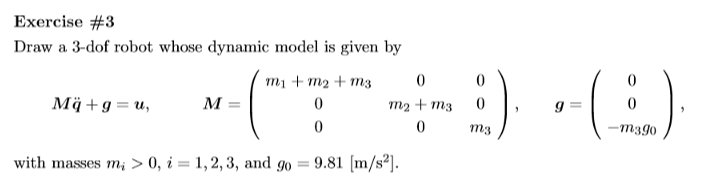

% 
% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [1,1,1];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% % alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

% R2Robot=['ppp';'xyz';sigmaD]

R2Robot = 3×3 char array
    'ppp'
    'xyz'
    ''


% z = Gen_param(n);
% z.sigmaD=R2Robot;
% % l(1)=0 %don't do this because dc1 is going to dissaperar
% % z.opt_expr={[l(1)],[0]};%use this instead
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table, 1 normal mode

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
     

% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% 
% % z.rcdefined=true;
% % z.prismatic_CoM_method(2)=2; %apy attention to this
% z.xyonly=true

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 1 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
     

% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% % % % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% % % %             0       , z.l(2)  , 0   , q(2);]

% % % % 
% % % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 1 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
     

si falla aquí está el error


anglerot = 1×1 cell array
    {4×4 sym}


method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \left(\begin{array}{ccc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} & \frac{m_{3}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}+{{\dot{q}}_{3}}^{2}\right)}{2} \end{array}\right)$$

$$To\_derive = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right)\\ q_{3}\left(t\right) \end{array}\right)$$

    "check the _ last term it is needed for the function for example q_1_ should be the right way to define a varaible to convert to time dependent"



z_derivated = struct with fields:
    dot_t: [3×3 sym]


z_derivated = struct with fields:
     dot_t: [3×3 sym]
    ddot_t: [3×3 sym]


z_derivated = struct with fields:
     dot_t: [3×3 sym]
    ddot_t: [3×3 sym]
    tdot_t: [3×3 sym]


z_derivated = struct with fields:
        dot_t: [3×3 sym]
       ddot_t: [3×3 sym]
       tdot_t: [3×3 sym]
          dot: [3×3 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×3 sym]
       ddot_t: [3×3 sym]
       tdot_t: [3×3 sym]
          dot: [3×3 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×3 sym]
        ddot_t: [3×3 sym]
        tdot_t: [3×3 sym]
           dot: [3×3 sym]
     dot_short: []
          ddot: [3×3 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×3 sym]
        ddot_t: [3×3 sym]
        tdot_t: [3×3 sym]
           dot: [3×3 sym]
     dot_short: []
          ddot: [3×3 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×3 sym]
        ddot_t: [3×3 sym]
        tdot_t: [3×3 sym]
           dot: [3×3 sym]
     dot_short: []
          ddot: [3×3 sym]
    ddot_short: []
          tdot: [3×3 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×3 sym]
        ddot_t: [3×3 sym]
        tdot_t: [3×3 sym]
           dot: [3×3 sym]
     dot_short: []
          ddot: [3×3 sym]
    ddot_short: []
          tdot: [3×3 sym]
    tdot_short: []


$$Pc = \left(\begin{array}{ccc} q_{1} & q_{1} & q_{1}\\ 0 & q_{2} & q_{2}\\ 0 & 0 & q_{3} \end{array}\right)$$

$$vc = \left(\begin{array}{ccc} {\dot{q}}_{1} & {\dot{q}}_{1} & {\dot{q}}_{1}\\ 0 & {\dot{q}}_{2} & {\dot{q}}_{2}\\ 0 & 0 & {\dot{q}}_{3} \end{array}\right)$$

$$w = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$T = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{3}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}+{{\dot{q}}_{3}}^{2}\right)}{2}+\frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$

$$Ti = \left(\begin{array}{ccc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2} & \frac{m_{3}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}+{{\dot{q}}_{3}}^{2}\right)}{2} \end{array}\right)$$

$$M = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & 0 & 0\\ 0 & m_{2}+m_{3} & 0\\ 0 & 0 & m_{3} \end{array}\right)$$

VarShortRobot = struct with fields:
    Pc: [3×3 sym]
    vc: [3×3 sym]
     w: [3×3 sym]
     T: [1×1 sym]
    Ti: [1×3 sym]
     M: [3×3 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×3 sym]
               TPartial: {[4×4 sym]  [4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×3 sym]
    Jacobian_dot_PTotal: [3×3 sym]
               PPartial: {[3×1 sym]  [3×1 sym]  [3×1 sym]}
                     Pc: [3×3 sym]
                RTotali: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
           ThetaPartial: [3×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×3 sym]
                      w: [3×3 sym]
                      T: [1×1 sym]
                     Ti: [1×3 sym]
                      M: [3×3 sym]


% Ti(1)
% T
% Pc
% M


## Exercise 4

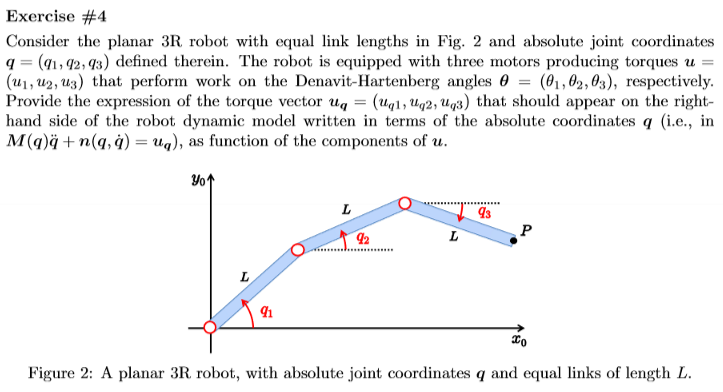



% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [0,0,0];
n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
g0 = sym('g0','real');
g=[0,-g0,0]';

R2Robot=['rrr';'xxx';sigmaD]

R2Robot = 3×3 char array
    'rrr'
    'xxx'
    '   '


z = Gen_param(n);
z.sigmaD=R2Robot;
% l(1)=0 %don't do this because dc1 is going to dissaperar
% z.opt_expr={[l(1)],[0]};%use this instead
z.l=l;
z.q=q;
z.q_dot=q_dot;
z.q_ddot=q_ddot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table, 1 normal mode

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
     

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));

% z.rcdefined=true;
% z.prismatic_CoM_method(2)=2; %apy attention to this
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 1 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
     

z.global_q_reference=true %global referenes

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 1 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 1
                 ismotor: 0
     

z.q_global=z.q;
z.q_dot_global=z.q_dot;
z.q_ddot_global=z.q_ddot;
% q = sym('q', [n,1],'real');
% qd= sym('qd', [n,1],'real');
% a = sym('a', [n,1],'real');
% d = sym('d', [n,1],'real');

% % % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% % %             0       , z.l(2)  , 0   , q(2);]

% % % 
% % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
[Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 1 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 1
                 ismotor: 0
     

si falla aquí está el error


$$a = l_{1}$$

d = 0

$$a = l_{2}$$

d = 0

$$a = l_{3}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \begin{array}{l} \left(\begin{array}{ccc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} & \frac{m_{3}\,\left({{\dot{q}}_{2}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+\sigma_{1}+{l_{2}}^{2}\right)+{{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{1}+\sigma_{1}+{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}\right)+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}+{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(2\,{{\mathrm{dc}}_{3}}^{2}+4\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2}+2\,l_{1}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+2\,{l_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,l_{2}\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{2}\,\cos\left(q_{3}\right)\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{1}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{3}\right)\right)\right)}{2}+\frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

$$To\_derive = \begin{array}{l} \left(\begin{array}{ccc} -l_{1}\,\sin\left(q_{1}\left(t\right)\right)-\sigma_{1}-l_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) & -\sigma_{1}-l_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) & -\sigma_{1}\\ l_{1}\,\cos\left(q_{1}\left(t\right)\right)+\sigma_{2}+l_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) & \sigma_{2}+l_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) & \sigma_{2}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)+q_{3}\left(t\right)\right)\\ \sigma_{2}=l_{3}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)+q_{3}\left(t\right)\right) \end{array}$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right)\\ q_{3}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×3 sym]


z_derivated = struct with fields:
     dot_t: [3×3 sym]
    ddot_t: [3×3 sym]


z_derivated = struct with fields:
     dot_t: [3×3 sym]
    ddot_t: [3×3 sym]
    tdot_t: [3×3 sym]


z_derivated = struct with fields:
        dot_t: [3×3 sym]
       ddot_t: [3×3 sym]
       tdot_t: [3×3 sym]
          dot: [3×3 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×3 sym]
       ddot_t: [3×3 sym]
       tdot_t: [3×3 sym]
          dot: [3×3 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×3 sym]
        ddot_t: [3×3 sym]
        tdot_t: [3×3 sym]
           dot: [3×3 sym]
     dot_short: []
          ddot: [3×3 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×3 sym]
        ddot_t: [3×3 sym]
        tdot_t: [3×3 sym]
           dot: [3×3 sym]
     dot_short: []
          ddot: [3×3 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×3 sym]
        ddot_t: [3×3 sym]
        tdot_t: [3×3 sym]
           dot: [3×3 sym]
     dot_short: []
          ddot: [3×3 sym]
    ddot_short: []
          tdot: [3×3 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×3 sym]
        ddot_t: [3×3 sym]
        tdot_t: [3×3 sym]
           dot: [3×3 sym]
     dot_short: []
          ddot: [3×3 sym]
    ddot_short: []
          tdot: [3×3 sym]
    tdot_short: []


$$Pc = \left(\begin{array}{ccc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) & l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

$$vc = \begin{array}{l} \left(\begin{array}{ccc} -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right) & -{\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)-{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right) & -{\dot{q}}_{1}\,\left(\sigma_{1}+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\sigma_{3}\right)-{\dot{q}}_{2}\,\left(\sigma_{1}+{\mathrm{dc}}_{3}\,\sigma_{3}\right)-{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\sigma_{3}\\ {\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) & {\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right) & {\dot{q}}_{1}\,\left(\sigma_{2}+l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\sigma_{4}\right)+{\dot{q}}_{2}\,\left(\sigma_{2}+{\mathrm{dc}}_{3}\,\sigma_{4}\right)+{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\sigma_{4}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{3}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$w = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ {\dot{q}}_{1} & {\dot{q}}_{1}+{\dot{q}}_{2} & {\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3} \end{array}\right)$$

$$T = \begin{array}{l} \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}+\frac{m_{3}\,\left({{\dot{q}}_{2}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+\sigma_{1}+{l_{2}}^{2}\right)+{{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{1}+\sigma_{1}+{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}\right)+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}+{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(2\,{{\mathrm{dc}}_{3}}^{2}+4\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2}+2\,l_{1}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+2\,{l_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,l_{2}\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{2}\,\cos\left(q_{3}\right)\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{1}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{3}\right)\right)\right)}{2}+\frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

$$Ti = \begin{array}{l} \left(\begin{array}{ccc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} & \frac{m_{3}\,\left({{\dot{q}}_{2}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+\sigma_{1}+{l_{2}}^{2}\right)+{{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{1}+\sigma_{1}+{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}\right)+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}+{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(2\,{{\mathrm{dc}}_{3}}^{2}+4\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2}+2\,l_{1}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+2\,{l_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,l_{2}\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{2}\,\cos\left(q_{3}\right)\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{1}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{3}\right)\right)\right)}{2}+\frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

$$M = \begin{array}{l} \left(\begin{array}{ccc} I_{1}+I_{2}+I_{3}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{2}}^{2}\,m_{3}+2\,{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)+2\,{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,\cos\left(q_{2}\right)+2\,{\mathrm{dc}}_{3}\,l_{2}\,m_{3}\,\cos\left(q_{3}\right)+2\,l_{1}\,l_{2}\,m_{3}\,\cos\left(q_{2}\right) & \sigma_{3} & \sigma_{1}\\ \sigma_{3} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+\sigma_{4}+m_{3}\,{l_{2}}^{2}+I_{2}+I_{3} & \sigma_{2}\\ \sigma_{1} & \sigma_{2} & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{3}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)+{\mathrm{dc}}_{3}\,l_{2}\,m_{3}\,\cos\left(q_{3}\right)\\ \sigma_{2}=m_{3}\,{{\mathrm{dc}}_{3}}^{2}+l_{2}\,m_{3}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}+I_{3}\\ \sigma_{3}=m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+\sigma_{4}+l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+m_{3}\,{l_{2}}^{2}+l_{1}\,m_{3}\,\cos\left(q_{2}\right)\,l_{2}+I_{2}+I_{3}\\ \sigma_{4}=2\,m_{3}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

VarShortRobot = struct with fields:
    Pc: [3×3 sym]
    vc: [3×3 sym]
     w: [3×3 sym]
     T: [1×1 sym]
    Ti: [1×3 sym]
     M: [3×3 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×3 sym]
               TPartial: {[4×4 sym]  [4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×3 sym]
    Jacobian_dot_PTotal: [3×3 sym]
               PPartial: {[3×1 sym]  [3×1 sym]  [3×1 sym]}
                     Pc: [3×3 sym]
                RTotali: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
           ThetaPartial: [3×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×3 sym]
                      w: [3×3 sym]
                      T: [1×1 sym]
                     Ti: [1×3 sym]
                      M: [3×3 sym]


Ti(1)

$$ans = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

T

$$T = \begin{array}{l} \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}+\frac{m_{3}\,\left({{\dot{q}}_{2}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+\sigma_{1}+{l_{2}}^{2}\right)+{{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{1}+\sigma_{1}+{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}\right)+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}+{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(2\,{{\mathrm{dc}}_{3}}^{2}+4\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2}+2\,l_{1}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+2\,{l_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,l_{2}\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{2}\,\cos\left(q_{3}\right)\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{1}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{3}\right)\right)\right)}{2}+\frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

Pc

$$Pc = \left(\begin{array}{ccc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) & l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

M

$$M = \begin{array}{l} \left(\begin{array}{ccc} I_{1}+I_{2}+I_{3}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{2}}^{2}\,m_{3}+2\,{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)+2\,{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,\cos\left(q_{2}\right)+2\,{\mathrm{dc}}_{3}\,l_{2}\,m_{3}\,\cos\left(q_{3}\right)+2\,l_{1}\,l_{2}\,m_{3}\,\cos\left(q_{2}\right) & \sigma_{3} & \sigma_{1}\\ \sigma_{3} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+\sigma_{4}+m_{3}\,{l_{2}}^{2}+I_{2}+I_{3} & \sigma_{2}\\ \sigma_{1} & \sigma_{2} & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{3}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)+{\mathrm{dc}}_{3}\,l_{2}\,m_{3}\,\cos\left(q_{3}\right)\\ \sigma_{2}=m_{3}\,{{\mathrm{dc}}_{3}}^{2}+l_{2}\,m_{3}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}+I_{3}\\ \sigma_{3}=m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+\sigma_{4}+l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+m_{3}\,{l_{2}}^{2}+l_{1}\,m_{3}\,\cos\left(q_{2}\right)\,l_{2}+I_{2}+I_{3}\\ \sigma_{4}=2\,m_{3}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$